%% Visualization for the data:
clc, clearvars, close all
addpath('data/')
healthy = readmatrix("data/data.xlsx",'Sheet','No.2WT'); % Healthy turbine
WT3 = readmatrix("data/data.xlsx",'Sheet','No.3');
faulty14 = readmatrix("data/data.xlsx",'Sheet','No.14WT');
faulty39 = readmatrix("data/data.xlsx",'Sheet','No.39WT');


WT3 data seems to not be in any consistent order compared to other datasets, and also has extra columns compared to them, so we are not using the data in this analysis. Dropping the last column from the healthy, because it is an extra quality variable and is not found from the remaining datasets.

healthy(:,end) = [];
labels = string(1:size(healthy, 2))

labels = 1×23 string array
    "1"    "2"    "3"    "4"    "5"    "6"    "7"    "8"    "9"    "10"    "11"    "12"    "13"    "14"    "15"    "16"    "17"    "18"    "19"    "20"    "21"    "22"    "23"




% Normalized datas:
norm_healthy = zscore(healthy)

norm_healthy =    19.3161   22.4222  -14.7858  -14.4251   -2.6424  -14.2765  -14.1415  -13.8713  -39.6106   -2.6461   -8.7066  -39.6106   39.5726    8.9950  -39.6106  -12.7578    5.4674  -39.2919  -39.5441    7.7059   -6.5801   31.3405    3.7970
    0.9516   -1.0941    0.1926   -0.1210    0.0371    0.0313    0.0464    0.0571    0.0239    0.0282    0.0659    0.0252   -0.0272    0.4543    0.0252   -1.3964    1.9607    0.0708    0.0733    0.4824    0.0519    0.9944   -1.6429
    0.3357   -0.3685    0.1926   -0.0936    0.0106    0.0386    0.0464    0.0546    0.0239    0.0005    0.0362    0.0252   -0.0272   -0.7658    0.0252   -1.3968    1.9607    0.0884    0.0733    0.4824   -0.0376    0.9944    0.4410
    1.5675   -0.9732    0.1926   -0.1044    0.0030    0.0313    0.0464    0.0471    0.0239   -0.0046    0.0186    0.0252   -0.0272   -0.7658    0.0252   -1.3968    1.9607    0.0708    0.0733    0.5700   -0.0376    0.9944   -0.0920
   -1.1015    0.7200    0.1926   -0.0936   -0.0320    0.0313 

norm_faulty14 = zscore(faulty14)

norm_faulty14 =    17.9997   20.0951   -2.0740   -2.2319   -0.9094   -3.0242   -2.9497   -2.9136       NaN   -0.8832   -0.7456   -0.9996   -0.7475    4.7588  -18.3272   -0.8788   -0.5793  -18.3099  -13.7666   -0.7940   -1.2530   -0.0517    2.5858   12.5217   -0.6531   -6.1058   -5.5521
    3.1837   -0.0566    1.1295    1.1565   -0.9325    1.6832    1.7023    1.7091       NaN   -0.9288   -0.6771   -0.9549    0.9262    0.0813    0.0540   -0.9432    1.2360    0.1456    0.0228    0.9195    0.9190    1.0184   -1.3340    1.0825    1.4097    2.2126    2.8063
   -4.4236   -0.4948    1.1295    1.1559   -0.9325    1.6778    1.6940    1.7036       NaN   -0.9288   -0.7496   -0.9549    0.9608    0.0813    0.0540   -0.9432    1.2334    0.1620    0.0228    0.9167    0.9218    1.0184   -1.6601    1.7336    1.4097    2.1733    2.7173
    2.0426    0.3817    1.1295    1.1555   -0.9325    1.6721    1.6911    1.6977       NaN   -0.9288   -0.7491   -0.9549    0.9640    0.0813    0.0540   -0.9432    1.2334 

norm_faulty39 = zscore(faulty39)

norm_faulty39 =    20.0030   23.4956  -11.7497  -11.8518   -1.3306  -13.0670  -12.1995  -12.6475  -11.8324   -1.3071   -1.4401   -1.4555   -0.3980   10.0677   -1.3957   -5.6249    3.3422  -26.0860  -19.7203   -0.0686   -1.6511    3.0883    3.9325   11.6707    2.1063   -5.2070   -5.0680
    3.9677    0.1030    1.8684    2.1615   -1.3561    2.2460    2.1675    2.0859   -1.2468   -1.3574   -1.3301   -1.4082    1.3642    0.3553   -1.4101    1.3749   -0.0354    0.0438    0.0509    1.6192    1.7007    2.6487   -1.2521    1.8436   -1.4129    2.3069    3.3696
   -3.4389   -0.7748    1.8634    2.1615   -1.3561    2.2299    2.1675    2.0743   -1.2468   -1.3574   -1.3750   -1.4082    1.4071    0.3553   -1.4101    1.3749   -0.0354    0.0790    0.0381    1.6290    1.7007    2.6487    1.1986    1.7172   -1.4129    2.2794    3.2991
    1.2167   -0.1478    1.8684    2.1615   -1.3561    2.2118    2.1675    2.0509   -1.2468   -1.3574   -1.4060   -1.4082    1.4128    0.3553   -1.4101    1.3749   -0.0354 

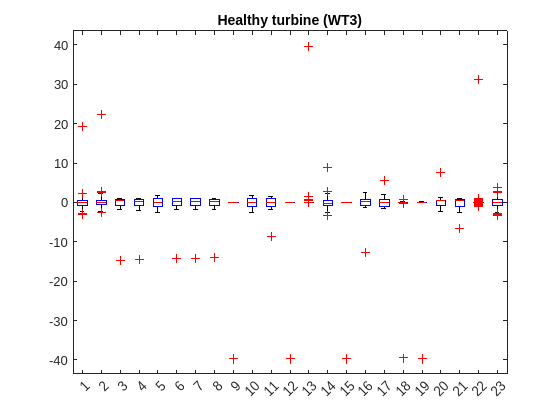


% Corresponding box plots:
boxplot(norm_healthy)
title('Healthy turbine (WT3)')

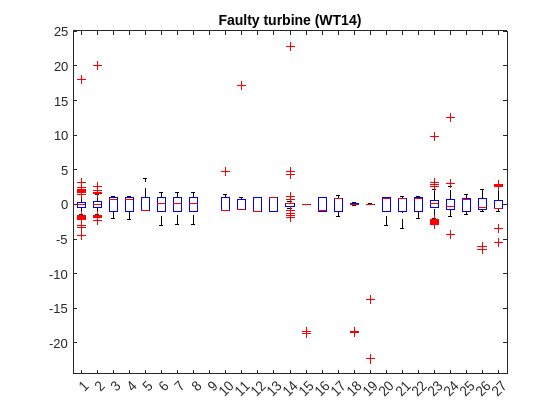

figure
boxplot(norm_faulty14)
title('Faulty turbine (WT14)')

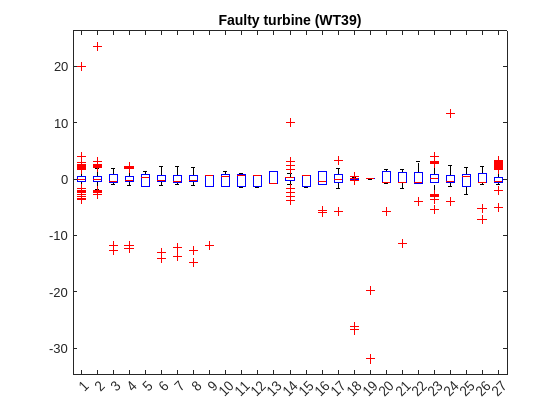

figure
boxplot(norm_faulty39)
title('Faulty turbine (WT39)')

#### Missing values

missing_2 = sum(isnan(healthy))

missing_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


missing_14 = sum(isnan(faulty14))

missing_14 =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


missing_39 = sum(isnan(faulty39))

missing_39 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Data Summary

mean_2 = mean(healthy);
mean_14 = mean(healthy);
mean_39 = mean(healthy);

min_2 = min(healthy);
min_14 = min(faulty14);
min_39 = min(faulty39);

max_2 = max(healthy);
max_14 = max(faulty14);
max_39 = max(faulty39);

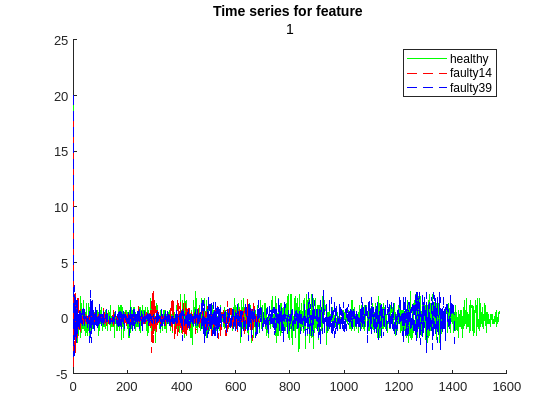

plotdata(norm_healthy,norm_faulty14,norm_faulty39,1)

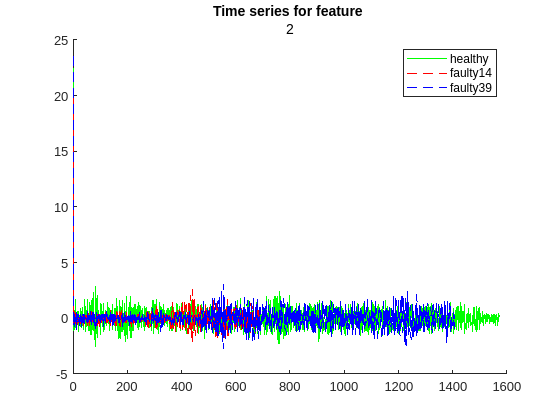


plotdata(norm_healthy,norm_faulty14,norm_faulty39,2)

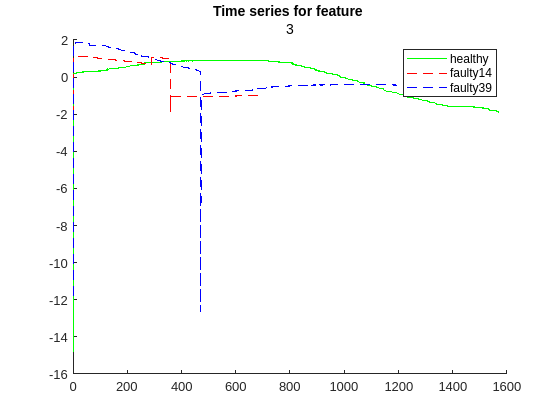


plotdata(norm_healthy,norm_faulty14,norm_faulty39,3)

## Data splitting

Splitting the data into calibration, validation and test sets

CALIBRATION_SIZE = 0.7;
VALIDATION_SIZE = 0.2;
TEST_SIZE = 0.1;

n_healthy_calib = floor(size(norm_healthy,1)*CALIBRATION_SIZE);
n_healthy_valid = floor(size(norm_healthy,1)*VALIDATION_SIZE);
n_healthy_test = size(norm_healthy,1) - (n_healthy_calib + n_healthy_valid);

norm_healthy_calib = norm_healthy(1:n_healthy_calib,:);
norm_healthy_valid = norm_healthy(1:n_healthy_valid,:);
norm_healthy_test = norm_healthy(1:n_healthy_test,:);


## PCA


model(1).X = norm_healthy_calib; %Pretreat data
[model(1).P, model(1).T, model(1).latent, model(1).T2all, model(1).explVar, model(1).mu] = pca(model(1).X);

figure; 
explVar = 100 * cumsum(model(1).latent(1:14)) / sum(model(1).latent(1:14));

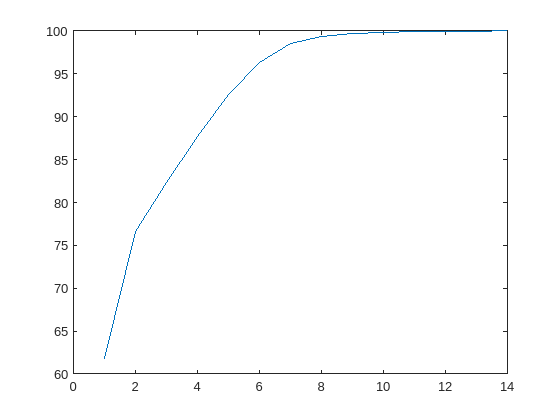

plot(1:14, explVar);

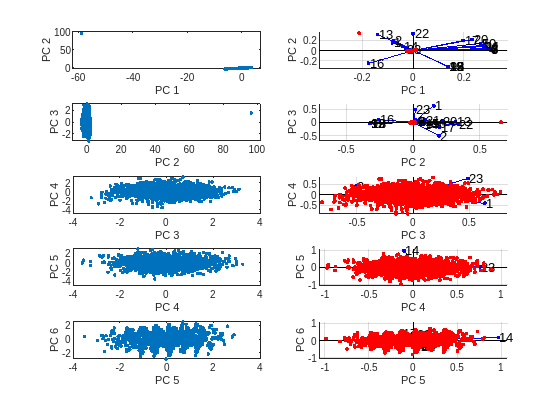

figure; 
ii = 1;

for i = 1:5

    subplot(5,2,ii);
    gscatter(model(1).T(:,i), model(1).T(:,i+1));
    text1 = "PC " + string(i);
    text2 = "PC " + string(i+1);
    xlabel(text1);
    ylabel(text2);
    ii      = ii + 1;

    subplot(5, 2, ii);
    biplot(model(1).P(:,i:(i+1)), 'Scores', model(1).T(:,i:(i+1)), 'VarLabels', labels);
    xlabel(text1);
    ylabel(text2);
    ii = ii + 1;
end

function [H] = plotdata(healthy,faulty14,faulty39,column)
    figure
    hold on
    plot(healthy(:,column),'g-')
    plot(faulty14(:,column),'r--')
    plot(faulty39(:,column),'b--')
    title('Time series for feature ',column)
    legend('healthy','faulty14','faulty39')
end
